# Actividad 1.9 (Landmarks)

Alan Iván Flores Juárez | A01736001

## Ejercicio 1

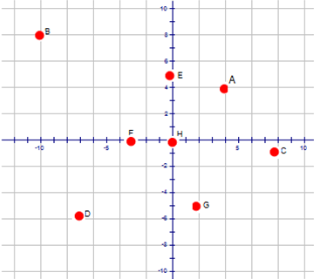

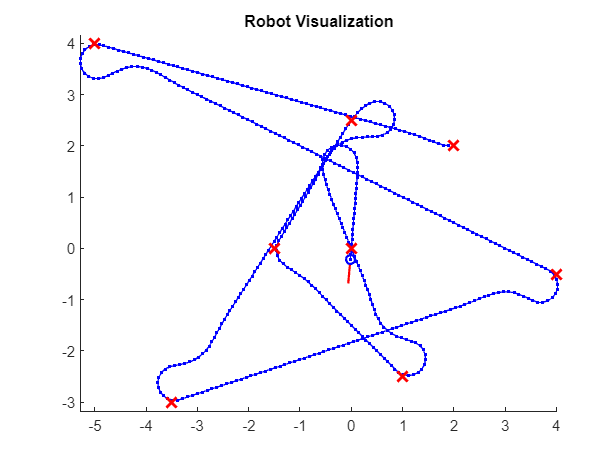

%% EXAMPLE: Differential drive vehicle following waypoints using the 
% Pure Pursuit algorithm
%
% Copyright 2018-2019 The MathWorks, Inc.

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:50;         % Time array

initPose = [2;2; pi];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [2,2; -5,4; 4,-0.5; -3.5,-3; 0,2.5; -1.5,0; 1,-2.5; 0,0];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 3;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints);
    waitfor(r);
    
end

## Ejercicio 2

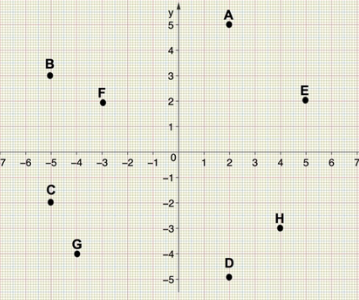

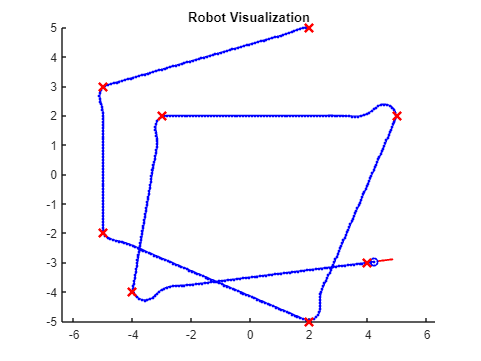

%% EXAMPLE: Differential drive vehicle following waypoints using the 
% Pure Pursuit algorithm
%
% Copyright 2018-2019 The MathWorks, Inc.

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:50.5;         % Time array

initPose = [2;5; pi];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [2,5; -5,3; -5,-2; 2,-5; 5,2; -3,2; -4,-4; 4,-3];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 2.5;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints);
    waitfor(r);
    
end

## Ejercicio 3

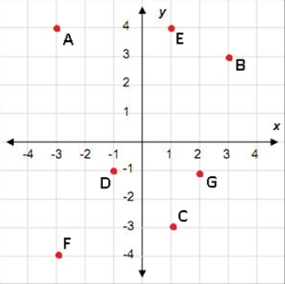

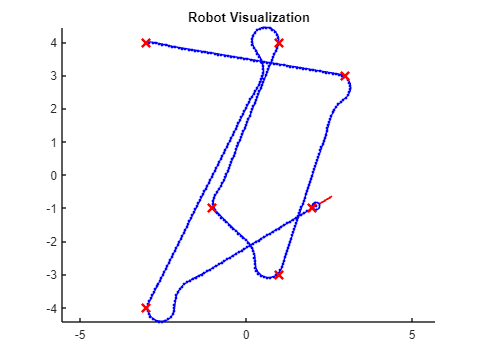

%% EXAMPLE: Differential drive vehicle following waypoints using the 
% Pure Pursuit algorithm
%
% Copyright 2018-2019 The MathWorks, Inc.

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:38;         % Time array

initPose = [-3;4; 0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [-3,4; 3,3; 1,-3; -1,-1; 1,4; -3,-4; 2,-1];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 2.5;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints);
    waitfor(r);
    
end

## Actividad 2

### Primera figura

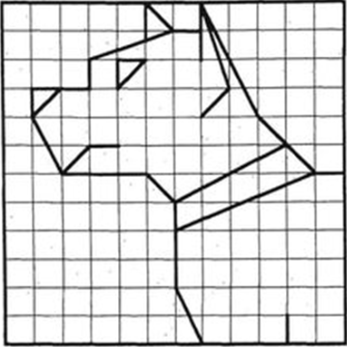

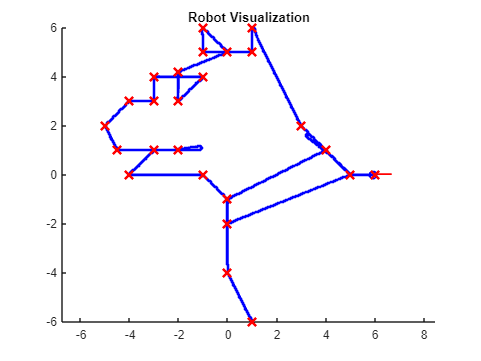

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:110;         % Time array

initPose = [1;-6; pi/2];        % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [1,-6; 0,-4; 0,-1; -1,0; -4,0; -3,1; -2,1; -4.5,1; -5,2; -4,3; -3,3; -3,4;-1,4; -2,3; -2,4.2; 0,5; -1,6; 
            -1,5; 1,5; 1,6; 3,2; 4,1; 0,-1; 0,-2; 5,0; 4,1;5,0; 6,0];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.2;
controller.DesiredLinearVelocity = 0.5;
controller.MaxAngularVelocity = 8;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints);
    waitfor(r);
    
end

### Segunda figura

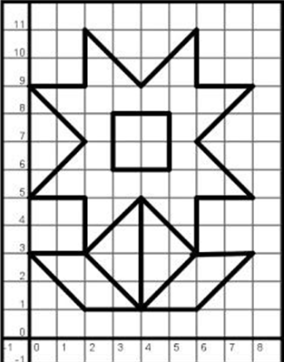

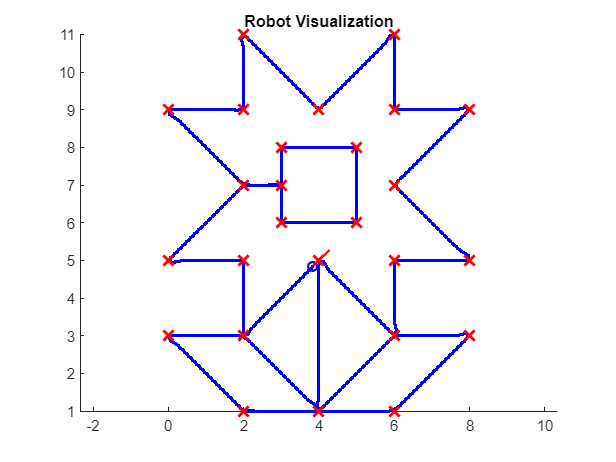

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:145;         % Time array

initPose = [2;1; 0];        % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [2,1; 4,1; 2,3; 0,3; 2,1; 6,1; 8,3; 6,3; 4,1; 4,5; 6,3; 6,5; 8,5; 6,7; 8,9; 6,9; 6,11; 4,9; 2,11; 2,9; 0,9; 2,7; 
             3,7; 3,8; 5,8; 5,6;3,6; 3,7; 2,7;0,5; 2,5; 2,3; 4,5];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.2;
controller.DesiredLinearVelocity = 0.5;
controller.MaxAngularVelocity = 7;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints);
    waitfor(r);
    
end

### Tercera figura

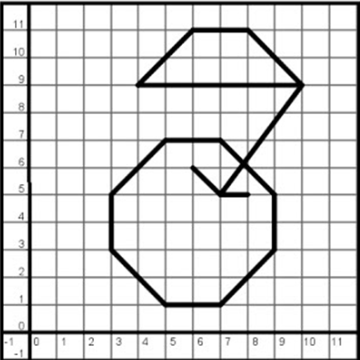

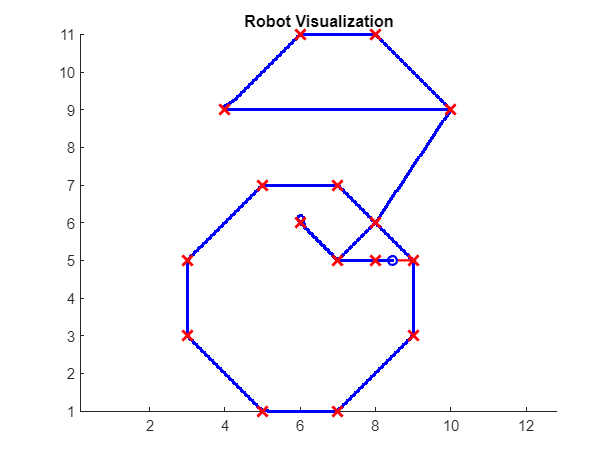

%% Define Vehicle
R = 0.05;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:85;         % Time array

initPose = [10;9; pi];        % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [10,9; 4,9; 6,11; 8,11; 10,9; 8,6; 7,7; 5,7; 3,5; 3,3; 5,1; 7,1; 9,3; 9,5; 8,6; 7,5; 6,6; 7,5; 8,5];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.15;
controller.DesiredLinearVelocity = 0.5;
controller.MaxAngularVelocity = 7;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints);
    waitfor(r);
    
end

## Pasos a seguir para el trazado de trayectorias

Uno de los aspectos más importantes para el trazado de trayectorias es la selección del origen del robot, así como su ángulo de salida, despúes acerciorarse que los puntos de las trayectorias esten correctamente colocadas y que sigan un orden, posteriormente es colocar valores adecuados para las velocidades, especialmente para la velocidad angular, ya que si la figura cuenta con giros cerrados y nuestra velocidad angular es baja, el robot trazará trayectorias circulares a través del punto o waypoint, resultando en una figura con circulos y no trazos rectos. 